# Conditional optimization (minimum search)

In many cases the optimum (minimum or maximum) of a function is searched withing a given range defined by several conditions. This script introduces conditional minimum search in Matlab.

## Rosenbrock function

Let's find the minimum of a [Rosenbrock function](https://en.wikipedia.org/wiki/Rosenbrock_function) that has the following generic form: $f(x,y) = (a - x)^2 + b(y - x^2)^2 $ with $a$ and $b$ paramters. We implement the function in a separate file: [`genericRosenbrock.m`](http://genericrosenbrock.m)

In the case of multidimensional functions, the `fminsearch` works in the same way, but the independent variables of the function along which the minimum is searched have to be put into a vector. 

Let's create the function handle of a Rosenbrock function with $a = 1$ and $b = 100$ parameters:

aParam = 1;
bParam = 100;
rosenbrockFcnHandle = @(xValues, yValues) genericRosenbrock(xValues, yValues, aParam, bParam);

### Evaluating the Rosenbrock function over the $x-y$ plane

Resolution:

resolution = 0.5;

Limes:

lim = 10;

Creating grid representation of the $x-y$ plane:

[xGrid, yGrid] = meshgrid(-lim:resolution:lim, -lim:resolution:5*lim);

Computing function values:

zValues = rosenbrockFcnHandle(xGrid, yGrid);

## Conditional optimization

The conditional minimum search can be performed by [`fmincon`](https://www.mathworks.com/help/optim/ug/fmincon.html) Matlab built-in function that finds the minimum of a problem specified by


$$\min_x f(x) \text{\ such that} \begin{cases}
c(x) < 0 \\
c_{eq}(x) = 0 \\
A \cdot x \leq b \\
A_{eq} \cdot x = b_{eq} \\
l_b \leq x \leq u_b
\end{cases}$$
 

including nonlinear inequality and equality, linear inequality and equality and boundary conditions.

In the following example, the minimum of the pre-defined Rosenbrock function is searched within a circle on the $x-y
$ plane given by a nonlinear inequality constraint. The other types of conditions are neglected in this example, since it is much more straightforward to define them. However, you can check some other examples in the [documentation](https://www.mathworks.com/help/optim/ug/fmincon.html) of `fmincon`.

### Setting optimization options

optimOpts = optimoptions('fmincon',...
                    'Algorithm', 'interior-point',...
                    'Display', 'iter',...
                    'OptimalityTolerance', 1e-6);

### Initial point of optimization

X0 = [0, 0];

### Function handle for the condition

The optimum value should be within the circle:

circleRadius = 3;
xCenter = 1;
yCenter = 2;

conditionFcnHandle = @(X) onCircle(circleRadius, xCenter, yCenter, ...
    X(1), X(2));

### Function handle for the optimization

optimFcnHandle = @(X) rosenbrockFcnHandle(X(1), X(2));

### Run optimization

[optimPlace, optimValue] = fmincon(optimFcnHandle, X0, ...
    [], [], [], [], [], [], ...
    conditionFcnHandle, optimOpts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.000000e+00    4.000e+00    1.600e+00
    1      16    1.039444e+00    3.920e+00    1.497e-01    2.210e-02
    2      20    1.139974e+00    3.828e+00    4.539e-01    4.419e-02
    3      27    1.822348e+00    3.498e+00    1.808e+00    8.839e-02
    4      31    3.957373e+00    3.063e+00    9.842e+00    1.768e-01
    5      36    1.560672e+01    2.257e+00    3.540e+01    2.015e-01
    6      39    8.033972e+01    5.448e-01    6.320e+01    7.381e-01
    7      42    6.398036e+01    7.794e-03    1.640e+00    8.828e-02
    8      45    6.375606e+01    7.925e-06    2.341e-01    2.815e-03
    9      48    6.375571e+01    1.967e-06    5.069e-02    1.402e-03
   10      51    6.375565e+01    1.198e-08    6.119e-05    1.094e-04

Local minimum found that satisfies the cons

## Computing function values on the circle boundary

alpha = 0 : 0.1*pi : 2.0 * pi;
xBoundaryPoints = circleRadius * sin(alpha) + xCenter;
yBoundaryPoints = circleRadius * cos(alpha) + yCenter;
zBoundaryValues = rosenbrockFcnHandle(xBoundaryPoints, yBoundaryPoints);

## Plotting the results

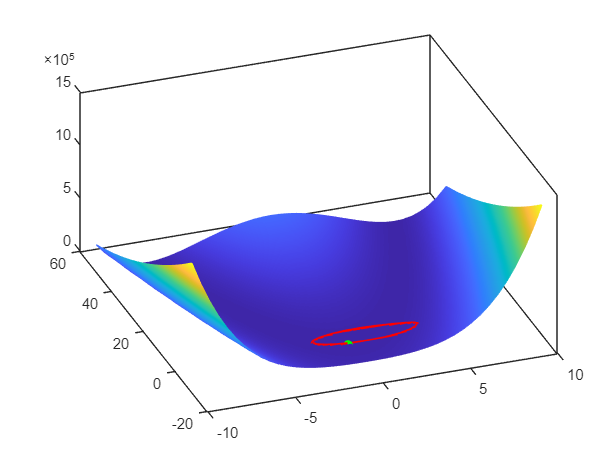

fig = figure();
ax = axes(fig);
hold(ax, 'on');
box(ax, 'on');
% Surface
surf(ax, xGrid, yGrid, zValues, ...
    'EdgeColor', 'interp', 'FaceColor', 'interp');
% Circle boundary
plot3(xBoundaryPoints, yBoundaryPoints, zBoundaryValues, 'r-', ...
    'LineWidth', 3);
% Optimum point
plot3(optimPlace(1), optimPlace(2), optimValue, 'go', ...
    'MarkerFaceColor', 'g');

% Setting view options (azimuth, elevation)
view([-20, 47]);

## Boundary function -> the optimum value is searched within this function

function [c, ceq] = onCircle(radius, circleCenterX, circleCenterY, ...
    xPoints, yPoints)
% The x-y optimum point should be within the circle defined by its 
% radius and center point (xo-yo)
% The square of the distance from the circle center should be less than the
% square of the circle radius (satisfies that the optimum will be within the circle)
% (x - xo)^2 + (y - yo)^2 = r^2
% (x - xo)^2 + (y - yo)^2 - r^2 = 0
ceq = (xPoints - circleCenterX)^2 + ...
    (yPoints - circleCenterY)^2 - radius^2; 
% if this value is less than 0, the optimum value will be witih the circle
c = []; % No inequality condition
end